# Demo script to run conductivity mapping using UCL MR-EPT 

Package has been tested on MATLAB 2022b

Last update: Jierong Luo 29th-Aug-2025 University College London

Download in-vivo data from: [UCL_MR-EPT_v2.3_in-vivo_examples](https://liveuclac-my.sharepoint.com/:f:/g/personal/rmapjlu_ucl_ac_uk/IgDRcUCNcZ6ZSK6RckALT0B-AdAjW9ASOzRUFqGpscXjVJk?e=Mmp8is)

addpath(genpath(fullfile('..', '..', 'functions')))


## Load Data 

data = load('Brain_invivo_gre_3T.mat');

b1plus_phase  = double(data.b1plus_phase); % load (measured or estimated) TRANSMIT (B1+) phase, i.e. phi0 / 2
mask          = double(data.mask);
segmentation  = double(data.segmentation); % (OPTIONAL) load tissue segmentations for Seg/Mag+Seg EPT
magnitude     = double(data.magnitude); % (OPTIONAL) load magnitude image for Mag/Mag+Seg EPT
magnitude_t1w = double(data.magnitude_t1w); % (OPTIONAL) load magnitude image for Mag/Mag+Seg EPT

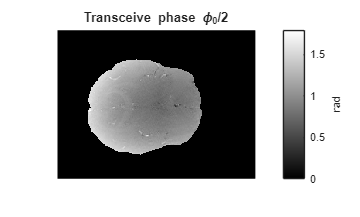

figure
imagesc(b1plus_phase(:,:,100))
colormap('gray')
axis equal; axis off
c = colorbar; 
c.Label.String = 'rad';
title('Transceive phase \phi_{0}/2')

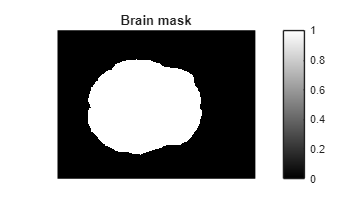


figure
imagesc(mask(:,:,100))
colormap('gray')
axis equal; axis off
colorbar; 
title('Brain mask')

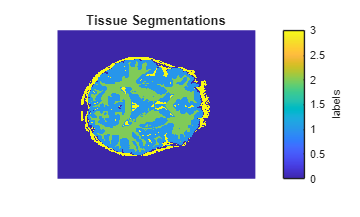


figure
imagesc(segmentation(:,:,100))
axis equal; axis off
c = colorbar; 
c.Label.String = 'labels';
title('Tissue Segmentations')

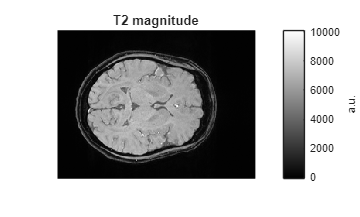


figure
imagesc(magnitude(:,:,100))
colormap('gray')
axis equal; axis off
c = colorbar; 
c.Label.String = 'a.u.';
title('T2 magnitude')

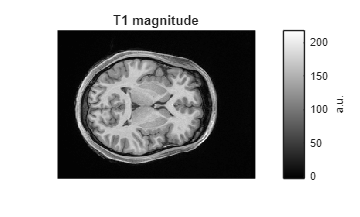


figure
imagesc(magnitude_t1w(:,:,100))
colormap('gray')
axis equal; axis off
c = colorbar; 
c.Label.String = 'a.u.';
title('T1 magnitude')

## Set up parameters

parameters.B0 = 3; % external magnetic field strength in [Tesla]
parameters.VoxelSize = [1 1 1]; % 3D [x,y,z] voxel size (resolution) in [MILLI-meter]
parameters.kDiffSize = [17 17 17]; % 3D [x,y,z] kernel size (diameter) for differentiation in [VOXEL]
parameters.kIntegralSize = [29 29 29]; % 3D [x,y,z] kernel size (diameter) for integration in [VOXEL]

## Surface-integral form T1w Mag+Seg EPT

% set up parallel computing
% parpool('Threads')

[conductivity, options] = conductivityMapping(b1plus_phase, mask, parameters, ...
    'magnitude', magnitude_t1w, 'segmentation', segmentation);

Magnitude and segmentation provided, using Mag+Seg EPT.
Starting parallel pool (parpool) using the 'Processes' profile ...
20-Sep-2026 15:27:36: Job Queued. Waiting for parallel pool job with ID 1 to start ...
Connected to parallel pool with 12 workers.


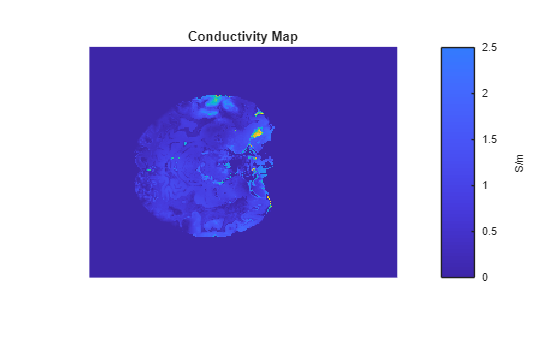


figure
imagesc(conductivity(:,:,100), [0 2.5])
axis equal; axis off
c = colorbar; 
c.Limits = [0 2.5];
c.Label.String = 'S/m';
title('Conductivity Map')